clc
clear all

imds=imageDatastore('Train','IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00000.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00001.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00002.png'
                               ... and 39206 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 39206 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


%dzielenie klasy na zbiory
[training, walidating, testing]=splitEachLabel(imds,0.7,0.15) 

training =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00000.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00001.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00002.png'
                               ... and 27443 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 27443 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


walidating =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00004_00027.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00004_00028.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00004_00029.png'
                               ... and 5888 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 5888 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


testing =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00005_00029.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00006_00000.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00006_00001.png'
                               ... and 5869 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 5869 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


testlabel=testing.Labels

testlabel = 5872×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


%ilosc class w sumie
classes=numel(categories(imds.Labels))

classes = 43

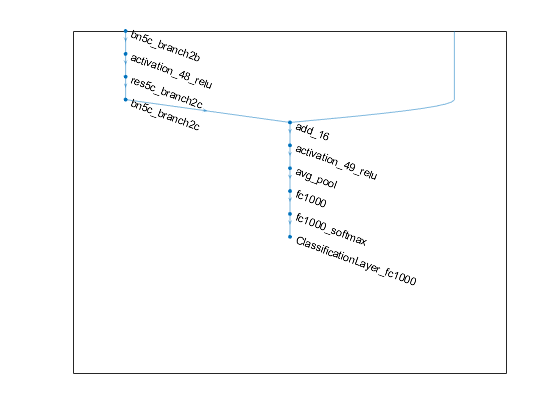

%zamienianie obrazu wejsciowego na wejscie resnet50
training=augmentedImageDatastore([224 224],training);
walidating=augmentedImageDatastore([224 224],walidating);
testing=augmentedImageDatastore([224 224],testing);

% wgrania ResNet-50.
net = resnet50;

% zamiana sieci na inny format aby moc zmieniac warstwy
lgraph = layerGraph(net);
figure
plot(lgraph)
ylim([-5 10])

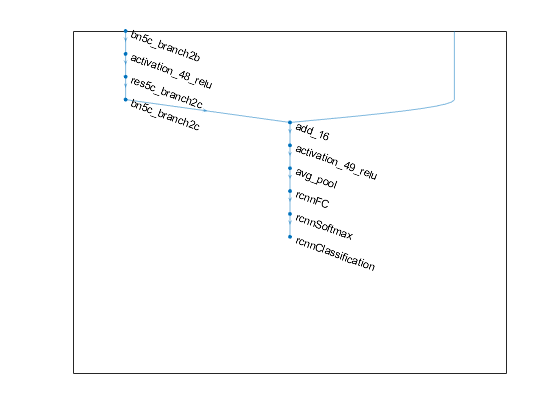

% usuniecie ostatnich 3 layers. 
layersToRemove = {
    'fc1000'
    'fc1000_softmax'
    'ClassificationLayer_fc1000'
    };

lgraph = removeLayers(lgraph, layersToRemove);
%dodawanie nowych klas klasyfikacyjnych
newLayers = [
    fullyConnectedLayer(classes, 'Name', 'FC')
    softmaxLayer('Name', 'Softmax')
    classificationLayer('Name', 'Classification')
    ];
lgraph = addLayers(lgraph, newLayers);
%polączenie nowych warstw
lgraph = connectLayers(lgraph, 'avg_pool', 'FC');
figure
plot(lgraph)
ylim([-5 10])


layers=lgraph

layers =   LayerGraph with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'rcnnClassification'}


%ustawienie tempo uczenia sie i maks epochs 10

options=trainingOptions('sgdm','InitialLearnRate',0.001,'MaxEpochs',2,'MiniBatchSize',32,'ValidationData',walidating)

options =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-03
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 2
               MiniBatchSize: 32
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: [1×1 augmentedImageDatastore]
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'none'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirectio

%uczenia sie
[signnet,info]=trainNetwork(training,layers,options)

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:56 |        0.00% |        1.14% |       4.3763 |       4.3176 |          0.0010 |
|       1 |          50 |       00:05:43 |       56.25% |       56.46% |       1.7275 |       1.7956 |          0.0010 |
|       1 |         100 |       00:09:32 |       84.38% |       79.04% |       0.7369 |       0.8526 |          0.0010 |
|       1 |         150 |       00:13:35 |       87.50% |       86.81% |       0.4881 |   

signnet =   DAGNetwork with properties:

         Layers: [177×1 nnet.cnn.layer.Layer]
    Connections: [192×2 table]
     InputNames: {'input_1'}
    OutputNames: {'rcnnClassification'}


info = struct with fields:
               TrainingLoss: [1×1714 double]
           TrainingAccuracy: [1×1714 double]
             ValidationLoss: [1×1714 double]
         ValidationAccuracy: [1×1714 double]
              BaseLearnRate: [1×1714 double]
        FinalValidationLoss: 0.0490
    FinalValidationAccuracy: 98.7608


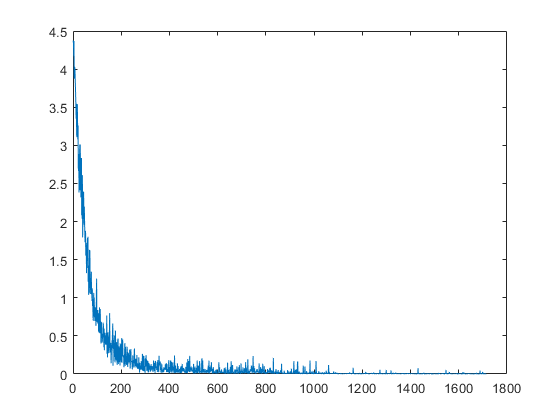


%wykres training loss
plot(info.TrainingLoss);

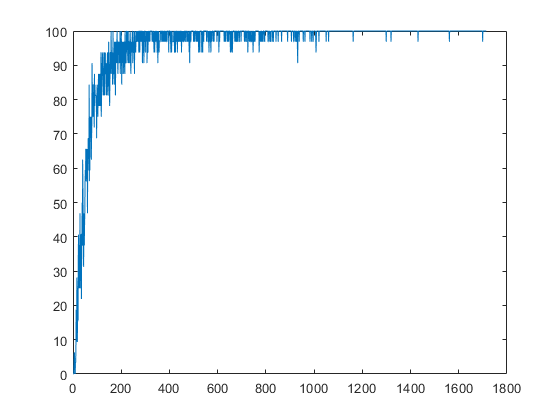

xlabel('Liczba iteracji')
ylabel('Strata małej partii')
%wykres traning dokładnosc
plot(info.TrainingAccuracy);

xlabel('Liczba iteracji')
ylabel('Dokładność procentowa[%]')
%testowanie sieci na 15 procent danych
testpreds=classify(signnet,testing)

testpreds = 5872×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


testactual=testlabel;
%ilośc dobrze sklasyfikowanych
numCorrect = nnz(testpreds == testactual)

numCorrect = 5756

%procent prawidłowo sklasyfikowanych
fracCorrect = numCorrect/numel(testpreds)

fracCorrect = 0.9802

%macierz pomyłek
fig = figure(1);
cc=confusionchart(testlabel,testpreds,'RowSummary','row-normalized','ColumnSummary','column-normalized')

cc =   ConfusionMatrixChart with properties:

    NormalizedValues: [43×43 double]
         ClassLabels: [43×1 categorical]

  Show all properties


xlabel('Klasy przewidziane')
ylabel('Klasy faktyczne')
cc.NormalizedValues

ans =     31     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   332     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   301     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   198     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

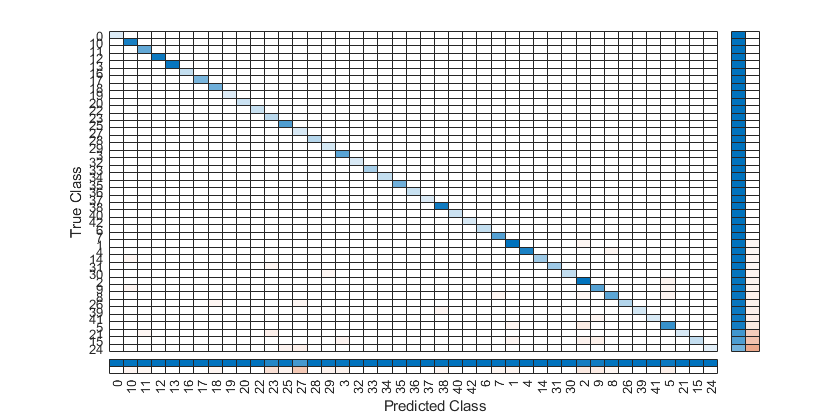

fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;
%sortuje według czułości na osi x
cc.Normalization = 'row-normalized'; 
sortClasses(cc,'descending-diagonal')
cc.Normalization = 'absolute'; 

% sortuje według precyzji na osi x
fig2=figure(2);
cc=confusionchart(testlabel,testpreds,'RowSummary','row-normalized','ColumnSummary','column-normalized')

cc =   ConfusionMatrixChart with properties:

    NormalizedValues: [43×43 double]
         ClassLabels: [43×1 categorical]

  Show all properties


xlabel('Klasy przewidziane')
ylabel('Klasy faktyczne')
cc.NormalizedValues

ans =     31     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   332     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   301     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   198     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

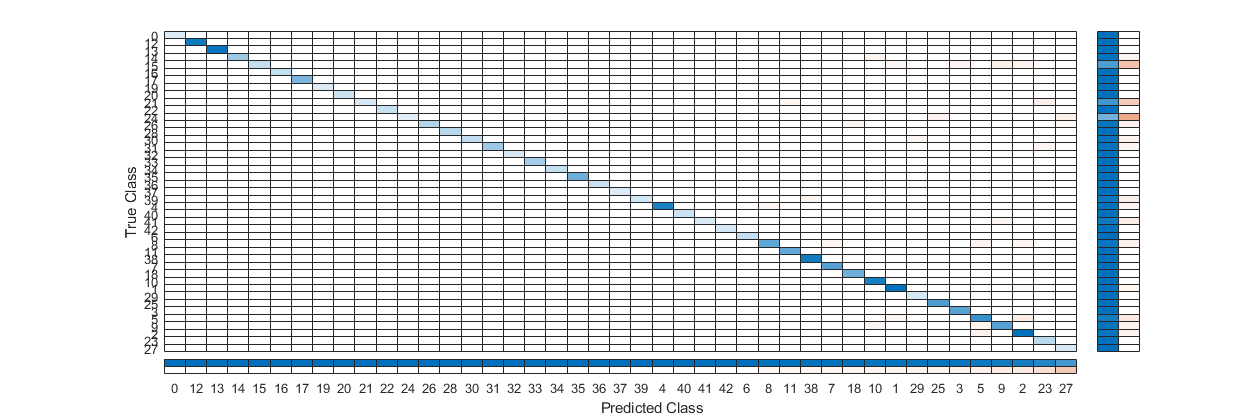

fig2_Position = fig.Position;
fig2_Position(3) = fig2_Position(3)*1.5;
fig2.Position = fig2_Position;
cc.Normalization = 'column-normalized';
sortClasses(cc,'descending-diagonal')
cc.Normalization = 'absolute';   